# §2-3  离散时间信号的表示及运算规则

#### 2-1 示例  用图示法来表示离散时间信号示例

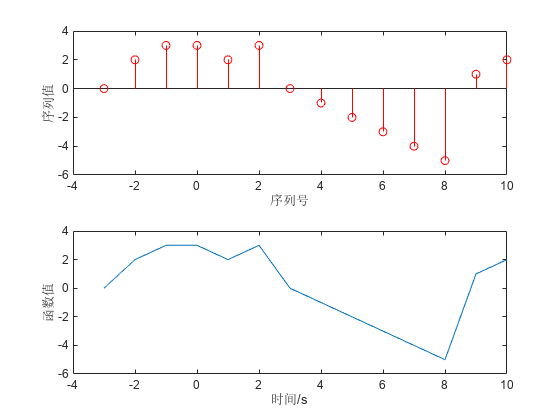

%序列序号
N = [-3 -2 -1 0 1 2 3 4 5 6 7 8 9 10];  

%序列值
X = [0 2 3 3 2 3 0 -1 -2 -3 -4 -5 1 2]; 

subplot(2,1,1);
%绘制离散值图
stem(N,X);  
hold on;

%绘制横轴
%用zeros(1,N)为产生1行N列元素值为零的数组，来绘制横轴，红色
%plot(N,zeros(1,length(X)),'r');

%产生坐标轴，设在方框上
%set(gca,'box','on');  
%2014早期版本用set，现在用图形对象
ss = stem(N,X);
ss.Color = 'red';

xlabel('序列号');
ylabel('序列值');

dt = 1;      %时间间隔（采样周期）
t = N*dt;    %时间序列
subplot(2,1,2);
plot(t,X);  %绘制随时间的变化
hold on;
%绘出横轴
%plot(t,zeros(1,length(X)),'r');  
xlabel('时间/s');
ylabel('函数值');

#### 2-2 示例  绘出原始信号和采样后的信号示例

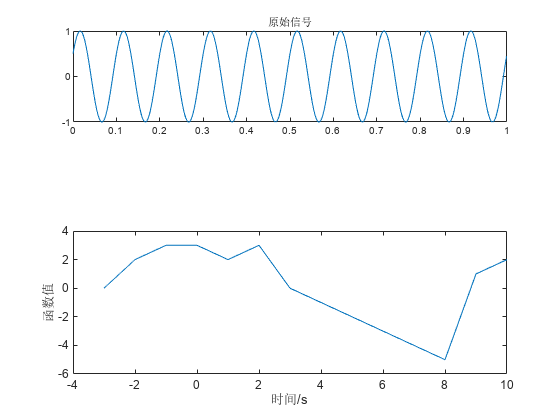

dt = 0.001;
n = 0:1000-1;
t = n*dt;
f = 10;                    %原始信号的频率为10Hz  x = sin(2*pi*ft)  
x = sin(2*pi*f*t + pi/6);  %在计算机上的原始信号
subplot(3,1,1);
plot(t,x);
% 绘出模拟原始信号,为与下图统一,采样y轴的范围[-1 1]用ylim给出
ylim([-1,1]);
title('原始信号');

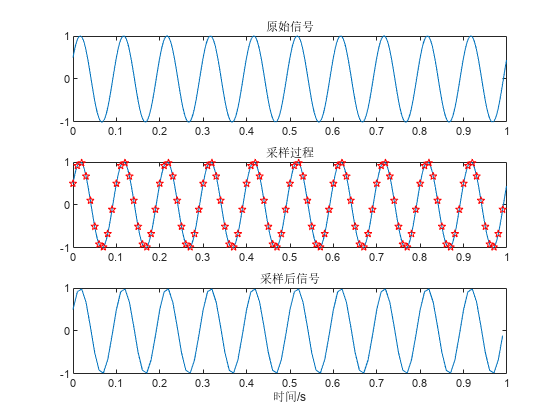


% 采样频率：100Hz
dt = 0.01; 
n = 0:100-1;
t1 = n*dt;

% 以100Hz的采样频率采样,为取一样的时间长度
% 序号长度为原始信号序号长度的1/10
x1 = sin(2*pi*f*t1 + pi/6);  %采样后的信号

% 绘出在模拟信号基础上的采样过程
subplot(3,1,2);
plot(t,x,t1,x1,'rp');
ylim([-1,1]);
title('采样过程');
%绘出采样后的信号

subplot(3,1,3);
plot(t1,x1);
ylim([-1,1]);
xlabel('时间/s');
title('采样后信号');

#### 2-3 示例  绘出单位采样序列示例

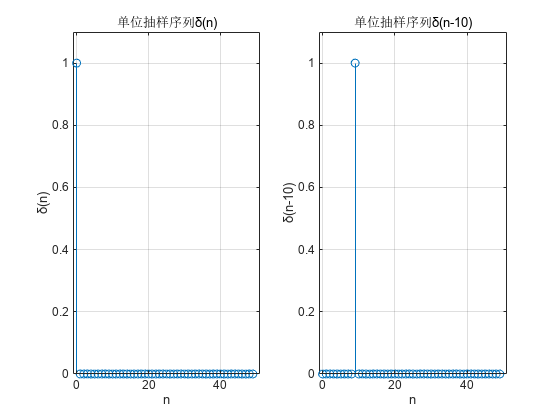

n=50;
x=zeros(1,n);
x(1)=1;
xn=0:n-1;
subplot(121);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位抽样序列δ(n)')
ylabel('δ(n)');
xlabel('n');
k=10;
x(k)=1;
x(1)=0;
subplot(122);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位抽样序列δ(n-10)')
ylabel('δ(n-10)');
xlabel('n');

#### 2-4 示例  绘出单位采样序列示例

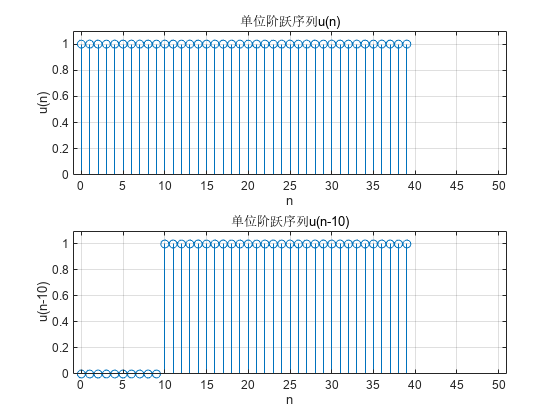

n=40;
x=ones(1,n);
xn=0:n-1;
subplot(211);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位阶跃序列u(n)')
ylabel('u(n)');
xlabel('n');

x=[zeros(1,10),1,ones(1,29)];
subplot(212);
stem(xn,x);
grid on     
axis([-1 51 0 1.1]);
title('单位阶跃序列u(n-10)')
ylabel('u(n-10)');
xlabel('n');

#### 2-5 示例  绘出正弦序列示例


$$\begin{array}{l}
\textrm{定义：}\\
x\left(t\right)=\textrm{Asin}\left(2\pi \;f*t+\theta \right)\\
x\left(\textrm{nT}\right)=\textrm{Asin}\left(2\pi \;f*\textrm{nT}+\theta \right)\\
x\left(n\right)=\textrm{Asin}\left(2\pi \;f/F_s *n+\theta \right)\\
\textrm{程序：}\\
x=A*\sin \left(2*\textrm{pi}*f_0 /F_s *n+\textrm{theta}\right)
\end{array}$$


试用Matlab绘制$x\left(n\right)=\sin \left(\frac{n\pi }{5}\right)$的波形图

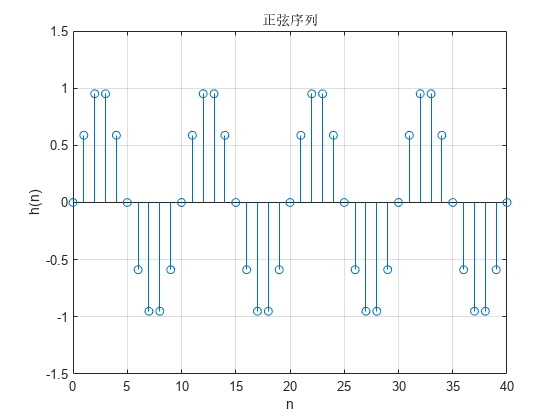

clear
n=0:59; 
x=sin(pi/5*n);
stem(n,x);
xlabel('n')
ylabel('h(n)')
title('正弦序列')
axis([0,40,-1.5,1.5]);
grid on;

#### 2-6 示例  卷积示例

创建两个向量并求其卷积。

u = [1 1 1];
v = [1 1 0 0 0 1 1];
w = conv(u,v)

w =      1     2     2     1     0     1     2     2     1


[卷积和多项式乘法 - MATLAB conv - MathWorks 中国](https://ww2.mathworks.cn/help/matlab/ref/conv.html?searchHighlight=conv&s_tid=srchtitle_support_results_1_conv)